**Martin Michaux (5701333)**

**Assignment 2 -> Questions 3-5**

data = table2array(readtable("dataexercise2.csv"))

data =     0.3668    0.7738   -0.3517   -0.7888    1.0000
    0.5239    2.1021    0.7871   -0.7156    6.0000
    0.2103    1.0691    0.5585    0.5619    1.0000
    0.8193    1.6103   -0.8128   -0.1293    9.0000
    0.5014    1.9799   -0.8055   -0.3423    3.0000
    0.5594    2.9724   -0.1054   -0.4052    8.0000
    0.5236    2.6627    0.4974    0.0003    2.0000
    0.4159    1.2459    0.1707    0.5294    6.0000
    0.5402    1.4927    0.0729   -0.1947         0
    0.6896    0.5877   -0.0903    0.6626    3.0000



x = data(:,1:4);
y = data(:,5);

n = height(data);
p = width(x);

Question 3:

Implement a Newton algorithm for computing the Laplace approximation to the posterior distribution.

newton_nbr_it = 100;

%aprior 
sigma = 4;
cov_matrix = sigma^2*eye(p);
thetas = [0 0 0 0];

for i=1:newton_nbr_it
    thetas = thetas + calculateGradient(x,y,thetas,cov_matrix)/calculateHessian(x,thetas,cov_matrix);
end

Report mean and covariance matrix of the approximation.

mean = thetas

mean =    -1.2870   -0.3880   -0.0222    0.0635


cov = -inv(calculateHessian(x,mean,cov_matrix))

cov =     0.0262   -0.0070    0.0007   -0.0009
   -0.0070    0.0028   -0.0002    0.0005
    0.0007   -0.0002    0.0136   -0.0013
   -0.0009    0.0005   -0.0013    0.0110


Question 4:

Implement a random-walk Metropolis Hastings algorithm to sample from the

posterior.

best_theta = mean

best_theta =    -1.2870   -0.3880   -0.0222    0.0635



sigma_proposal = 0.03;

c=0;
MH_nbr_it = 1000;
thetas = zeros(MH_nbr_it,4);
for i=1:MH_nbr_it        
    prop_theta = best_theta + sigma_proposal*mvnrnd([0 0 0 0],eye(p));

    prop_posterior = calculateLogPrior(prop_theta,eye(p))+calculateLogLik(x,y,prop_theta);
    best_posterior = calculateLogPrior(best_theta,sigma*eye(p))+calculateLogLik(x,y,best_theta);

    ratio = prop_posterior-best_posterior;
    alpha = min(1,max(0,ratio));

    u = rand;
    if u < alpha
        c=c+1;
        best_theta = prop_theta;
    end
    thetas(i,:) = best_theta;
end
display("Acceptance rate = "+c/MH_nbr_it)

    "Acceptance rate = 0.309"



Make a plot of the iterates where you plot $\theta_2$ versus $\theta_1$, with colour indicating the iteration number.

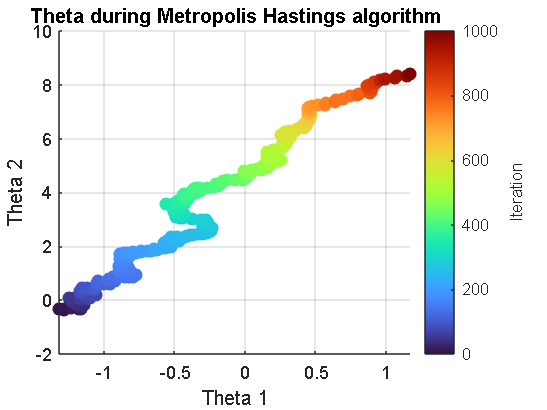

cmap = turbo(MH_nbr_it);
scatter(thetas(:,1),thetas(:,2),50,cmap, 'filled')
title('Theta during Metropolis Hastings algorithm')
xlabel('Theta 1')
ylabel('Theta 2')
grid on
colormap(cmap)
c = colorbar;
c.Label.String = 'Iteration';
caxis([0, MH_nbr_it])

Report the Monte-Carlo estimate of the posterior mean.

display("Monte Carlo estimate = ["+sum(thetas(:,1))/length(thetas(:,1))+','+sum(thetas(:,2))/length(thetas(:,2))+']')

    "Monte Carlo estimate = [0.044382,4.8425]"



Question 5:

Implement a Gibbs sampler that iteratively samples from the full conditionals of

$\theta$ and $\overset{~}{\sigma}$.

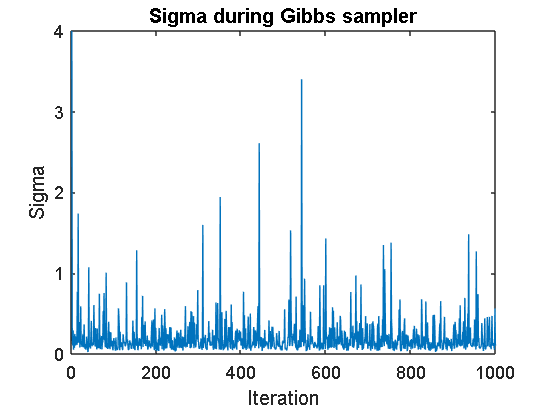

Gibbs_nbr_it = 1000;
b = 0.2;
a = 0.2;
sigma_proposal = 0.03;
sigma = 4;

sigmas = zeros(Gibbs_nbr_it,1);
sigmas(1)=sigma;
for i=2:Gibbs_nbr_it
    prop_theta = best_theta + sigma_proposal*mvnrnd([0 0 0 0],eye(p));

    prop_posterior = calculateLogPrior(prop_theta,eye(p))+calculateLogLik(x,y,prop_theta);
    best_posterior = calculateLogPrior(best_theta,sigma*eye(p))+calculateLogLik(x,y,best_theta);

    ratio = prop_posterior-best_posterior;
    alpha = min(1,max(0,ratio));

    u = rand;
    if u < alpha
        best_theta = prop_theta;
    end

    sigma = 1/gamrnd(a+(p/2),b+(norm(best_theta))/2);
    sigmas(i,:)=sigma;
end

plot(sigmas)
title('Sigma during Gibbs sampler')
xlabel('Iteration')
ylabel('Sigma')

function lambda = calculateLambda(x,theta)   
    lambda = exp(-x*transpose(theta));
end

function gradient = calculateGradient(x,y,theta,cov_matrix)
    n = height(x);

    gradient = 0;
    for i=1:n
        x_i = x(i,:);
        y_i = y(i,:);
        lambda_i = calculateLambda(x_i,theta);
        gradient = gradient + ((y_i-lambda_i)*x_i - theta/cov_matrix);
    end
end

function hessian = calculateHessian(x,theta,cov_matrix)
    n = height(x);

    hessian = 0;
    for i=1:n
        x_i = x(i,:);
        lambda_i = calculateLambda(x_i,theta);
        hessian = hessian - lambda_i*transpose(x_i)*x_i - inv(cov_matrix);
    end
end

function loglik = calculateLogLik(x,y,theta)
    n = height(x);
    
    loglik = 0;
    for i=1:n
        x_i = x(i,:);
        y_i = y(i,:);
        lambda_i = calculateLambda(x_i,theta);
        loglik = loglik + (-lambda_i+y_i*x_i*transpose(theta)-log(factorial(y_i)));
    end
end

function logprior = calculateLogPrior(theta,cov)
    logprior = log(mvnpdf(theta,[0 0 0 0],cov));
end